# Non-linear Gradient Demo

Non-linear gradients can be represented with spherical harmonics:

[https://onlinelibrary.wiley.com/doi/full/10.1002/mrm.20122](https://onlinelibrary.wiley.com/doi/full/10.1002/mrm.20122)

Where we calculate the true gradient field following Eq 4.  The $\alpha$ and $\beta$ coefficients from that equation are provided by the magnet vendor, which they have characterized for a given gradient coil construction. These characterizations are generally proprietary. For the example below we generated our own coefficients in a similar range to real values.

Original code creation by Michael Loecher. DBE@STANFORD.EDU (April 2020 for Rad229)

## Gradient Nonlinearity Demo Questions:

1) Are non-linear gradient effects worse at isocenter or distant from isocenter?

2) What are the maximum and minimum displacements induced by gradient non-linearity? Which gradient axis is most linear?

3) [Advanced] Can non-linear gradient behaviour be mitigated with gradient waveform re-design? Why or why not?

4) [Advanced] Discuss why gradients are generally non-linear? Why don't the manufacturers design more linear systems?

5) [Advanced] Use the provided non-linear gradient coeffients in a simulation to generate a distorted image during Cartesian fourier encoding.

## Define MRI System Constants and Acquisition Parameters

sys = Rad229_MRI_sys_config;          % Load system configuration
load('nonlinear_gradient_coeff.mat'); % Load pre-defined spherical harmonic coefficients

acq.FOVx = 500e-3;  % Field-of-view along x-direction [m]
acq.Nx = 32;       % Number of pixels to discretize FOVx [#]

pos_range = linspace(-acq.FOVx/2 , acq.FOVx/2 , acq.Nx); % Isotropic field-of-view [m]
[acq.x_pos, acq.y_pos, acq.z_pos] = ndgrid(pos_range , pos_range , pos_range); % Locations at which to calculate distortion [m]

## Calculating the Displacement (Distortion) Fields

Calculate the gradient field from the **spherical harmonics**. ***NOTE ****– This cell can take 10-20 seconds to run, you can lower N in this code block to make it go faster. *We then calculate the field at each of these locations.  This code is fairly complicated, but you can look at the [paper](https://onlinelibrary.wiley.com/doi/full/10.1002/mrm.20122) mentioned above and the Wikipedia page on [spherical harmonics](https://en.wikipedia.org/wiki/Spherical_harmonics) to learn more. 

x = 1000 * acq.x_pos; % Positions in  [mm]
y = 1000 * acq.y_pos; % Positions in  [mm]
z = 1000 * acq.z_pos; % Positions in  [mm]

[dx, dy, dz] = get_distortion(x, y, z, Alpha_x, Alpha_y, Alpha_z, Beta_x, Beta_y, Beta_z, R0);

These fields (dx, dy, dz) contain the gradient non-linearity induced error as a **displacement field **in [mm].  We can apply these fields to each location and calculate where the voxel has distorted to in the image.  

## Visualizing the Displacement (Distortion) Fields

The X, Y, or Z displacement depends on the position within the scanner. The displacments at isocenter are zero, but have complex shapes more distant from isocenter.

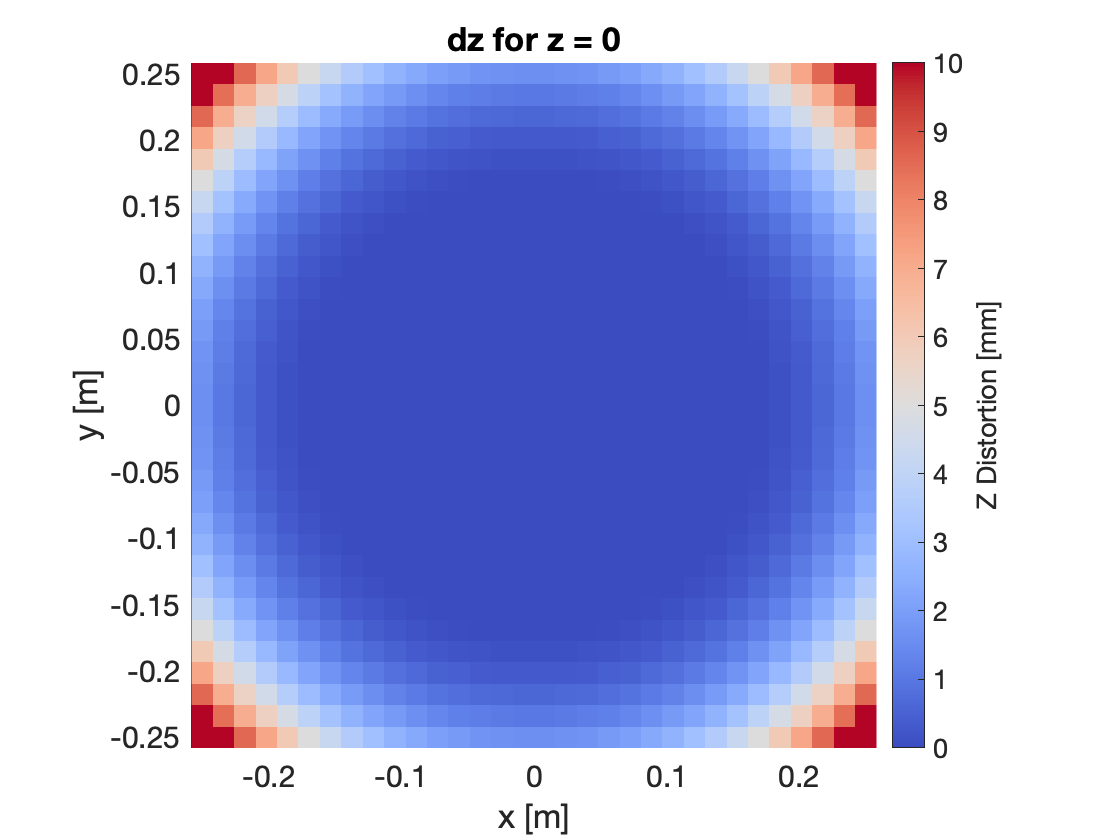

% Visualize the z-displacement (dz) for an XY-slice at isocenter.
figure; hold on;
  imagesc(pos_range , pos_range , squeeze( dz( : , : , acq.Nx / 2 ) ) );
  title('dz for z = 0'); xlabel('x [m]'); ylabel('y [m]');
  colormap(coolwarm);
  c = colorbar; caxis([0 10]); c.Label.String = 'Z Distortion [mm]';
  axis image;

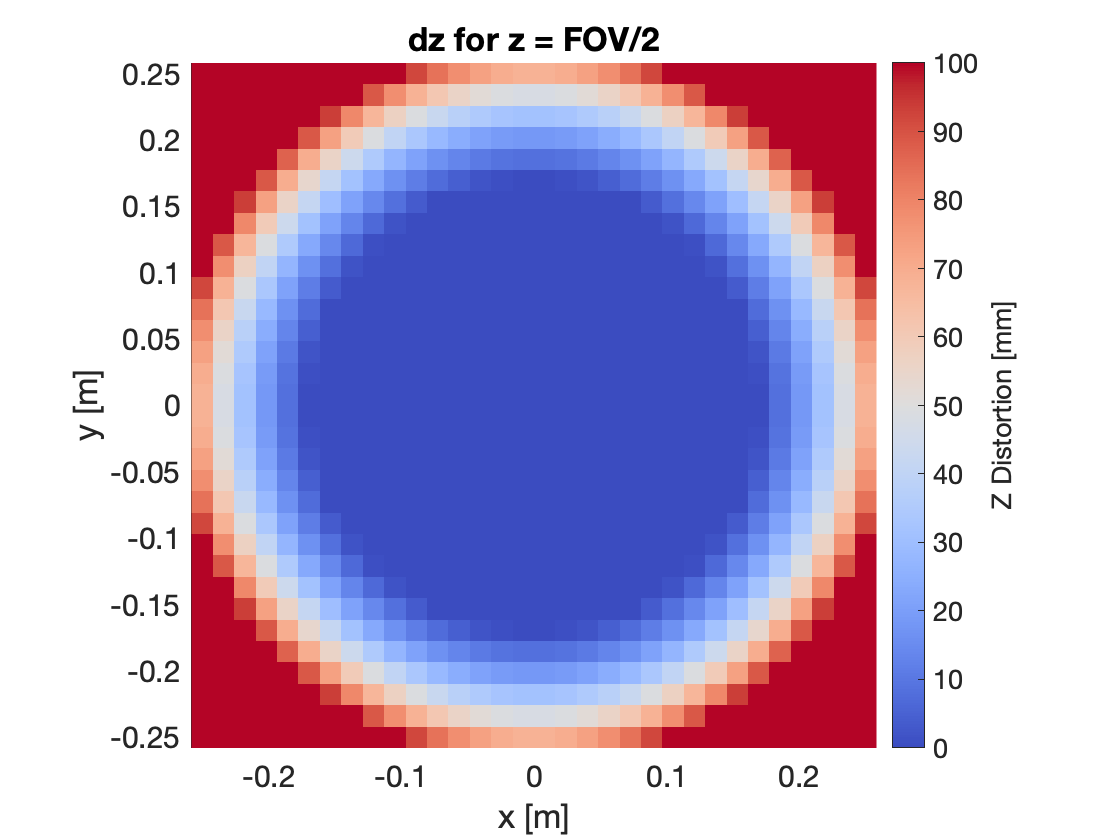


% Visualize the z-displacement (dz) for an XY-slice FOV/2 away from isocenter.
figure; hold on;
  imagesc(pos_range , pos_range , squeeze( dz( : , : , acq.Nx ) ) );
  title('dz for z = FOV/2'); xlabel('x [m]'); ylabel('y [m]');
  colormap(coolwarm);
  c = colorbar; caxis([0 100]); c.Label.String = 'Z Distortion [mm]';
  axis image;

You will notice that the **displacements errors are large** (10s of mm error at the edges). This is mostly because we are looking at a FOV that is much bigger than anything we would acquire clinically and the coefficients used to scale the effect. However, even with normal clinical FOVs, the uncorrected distortion can be significant (many [mm]).

## Visualize the Gradient Fields

We can calculate what the gradient field looks like by adding the distortion to our initial positions (positions are linearly related to the gradient field). Herein we see the **classic nonlinear gradient behavior**. While we expect (ideally) Gz to be consistent for all x and y positions, due to non-linearities it is not (as well as for Gx and Gy).

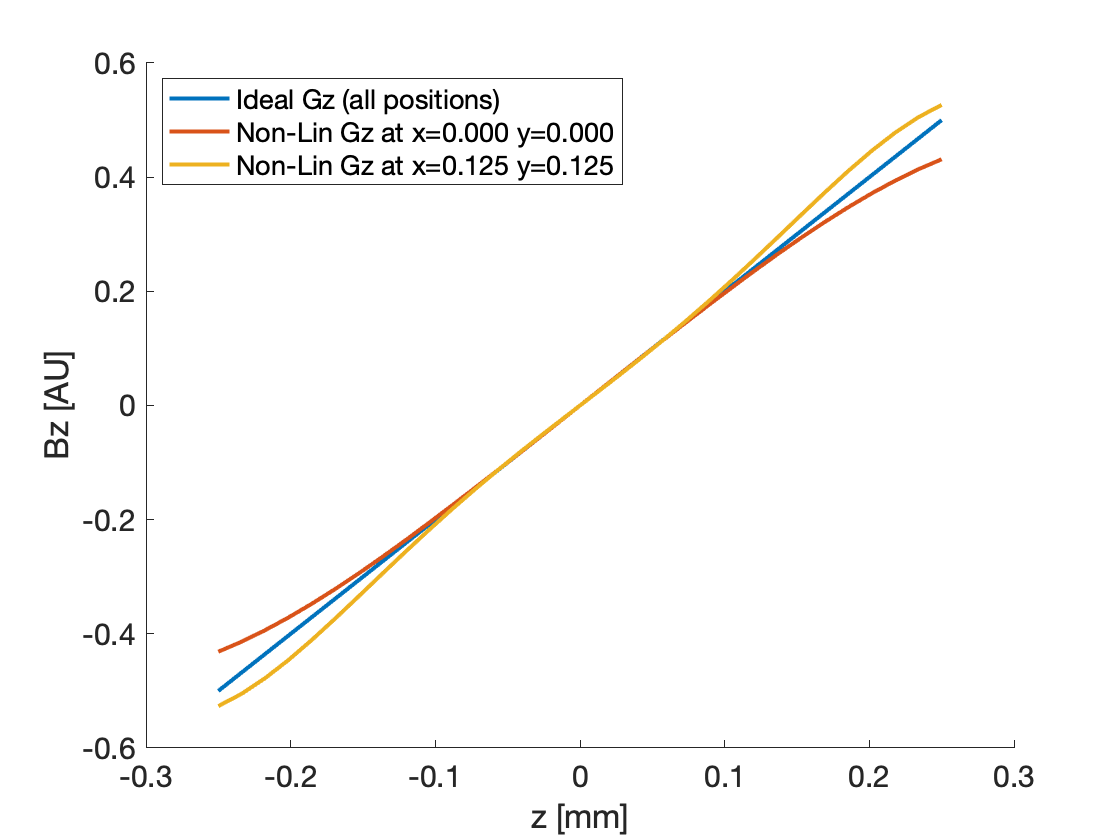

% These are the absolute positions in [m]
Px = acq.x_pos; % [m]
Py = acq.y_pos; % [m]
Pz = acq.z_pos; % [m]

% Scale these position values to create arbitrary magnetic field units. We cannot know the 'real' field, 
% i.e. milliTesla because the scaling could be anything and would be sequence specific.
Gx = Px / acq.FOVx; % [a.u]
Gy = Py / acq.FOVx; % [a.u]
Gz = Pz / acq.FOVx; % [a.u]

% Scale the distorted position values to distorted gradient field values
Gx_NonLin = (Px + dx / 1000) / acq.FOVx; % [a.u]
Gy_NonLin = (Py + dy / 1000) / acq.FOVx; % [a.u]
Gz_NonLin = (Pz + dz / 1000) / acq.FOVx; % [a.u]

% Compare the gradient fields [a.u.]
figure; hold on;
  plot(pos_range, squeeze(Gz(acq.Nx/2, acq.Nx/2, :)), 'LineWidth', 2);
  plot(pos_range, squeeze(Gz_NonLin(acq.Nx/2, acq.Nx/2, :)), 'LineWidth', 2);
  plot(pos_range, squeeze(Gz_NonLin(acq.Nx/4, acq.Nx/4, :)), 'LineWidth', 2);
  xlabel('z [mm]'); ylabel('Bz [AU]');
  legend('Ideal Gz (all positions)', 'Non-Lin Gz at x=0.000 y=0.000', 'Non-Lin Gz at x=0.125 y=0.125' , 'Location' , 'northwest');

## Create 3D Grid Phantom

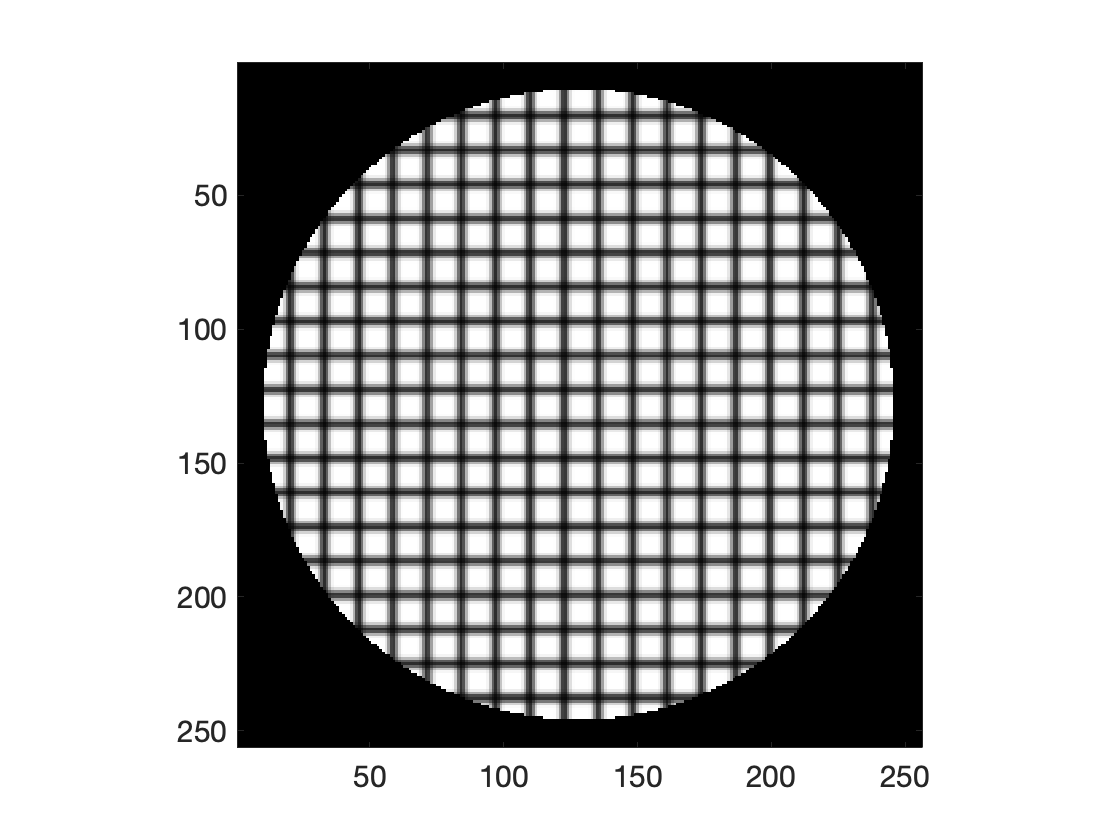

% Generate a 3D phantom with grid lines to help visualize distortion
imsize = 256; % In-plane number of voxels
Nz = 10; % Number of z-slices

im0 = grid_phantom(imsize);  % Generate a grid phantom image
im0 = repmat(im0 , [ 1 , 1 , Nz ]); % Make it 3D

figure;
  imagesc( im0( : , : , 1 ) );
  colormap(gray);
  axis image;

## Distort 3D Grid Phantom with Gradient Non-linearity

In this example the computed non-linear gradient distortion is computed and used to distort an object to demonstrate the effect. In practice, the acquired image is inherently distorted (owing to non-linear gradients) and the distorion is undone (inverted) because we know the gradient non-linearity.

Matlab coordinates [x,y,z = 1,2,3...255,256] to scanner coordinates [x,y,z = -FOV/2 to FOV/2 mm]transformation.

% Coordinates in Matlab 1-256 notation
[Vx, Vy, Vz] = ndgrid(1:size(im0,1), 1:size(im0,2), 1:size(im0,3));

% This maps the Matlab coordinates to the real world Right-Anterior-Superior (RAS) coordinate system. 
% So 1,3,2 is R (right), S (superior), A (anterior). So this will be a coronal slice:
coord_dirs = [1,3,2];

% This is the resolution in mm, in each Matlab dimension. We use unrealistically big slices to visualize 
% more FOV
res = [1.5, 1.5, 20.0];

% Get the transform matrix
coords = get_coords(coord_dirs, res, im0);

% Convert the Matlab coords to SCANNER coords
[Scn_x, Scn_y, Scn_z] = transform_coords(Vx, Vy, Vz, coords);

Calculate the distortion values for each of these voxel SCANNER positions. This can take a couple seconds.

% Get the distortion (Same code as above, just in a funcion)
[Scn_dx, Scn_dy, Scn_dz] = get_distortion(Scn_x, Scn_y, Scn_z, Alpha_x, Alpha_y, Alpha_z, Beta_x, Beta_y, Beta_z, R0);

% Get the distorted coordinates
Scn_x_distort = Scn_x + Scn_dx;
Scn_y_distort = Scn_y + Scn_dy;
Scn_z_distort = Scn_z + Scn_dz;

Apply the distortion by interpolating the distorted positions to pixel positions using a built-in Matlab function called scatteredInterpolant.

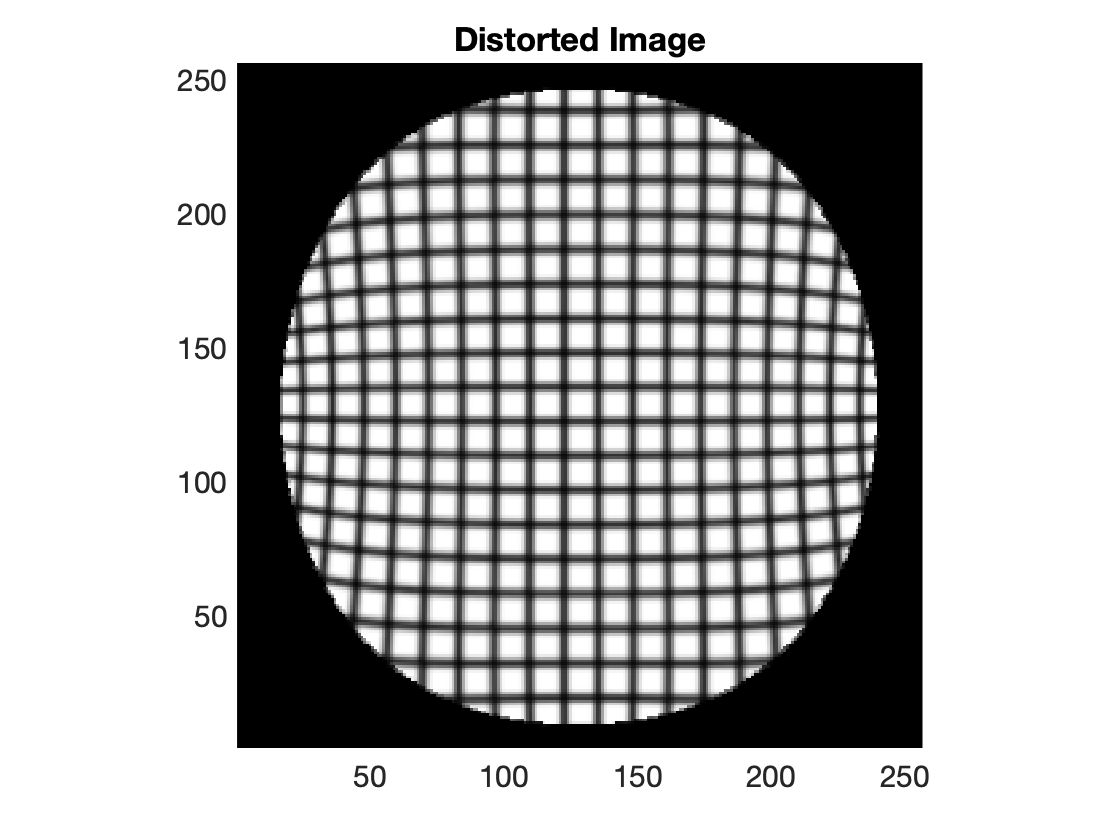

% We first convert back to the matlab coordinate system
[Vx_d, Vy_d, Vz_d] = transform_coords(Scn_x_distort, Scn_y_distort, Scn_z_distort, inv(coords));

% Then we interopolate each voxel in our image to their distorted position
F = scatteredInterpolant(Vx_d(:), Vy_d(:), Vz_d(:), im0(:));
im_d = F(Vx, Vy, Vz);

figure; hold on;
  imagesc( im_d( : , : , Nz/2 ) );
  colormap(gray); axis image;
  title('Distorted Image')